addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Part a) make the data and lagrange polynomials to make the overall interpolation polynomial. 

xData = [0.6 0.7 0.8 0.9]; 
yData = [0.58812 0.68122 0.77209 0.86047];

poly = interpLagrange(xData, yData)

$$poly = -\frac{13\,x^{3}}{300}-\frac{41\,x^{2}}{2000}+\frac{60761\,x}{60000}-\frac{11}{4000}$$

Part b) plot the polynomial that passes through the points 0.6 .. 0.9 by 0.01 separation

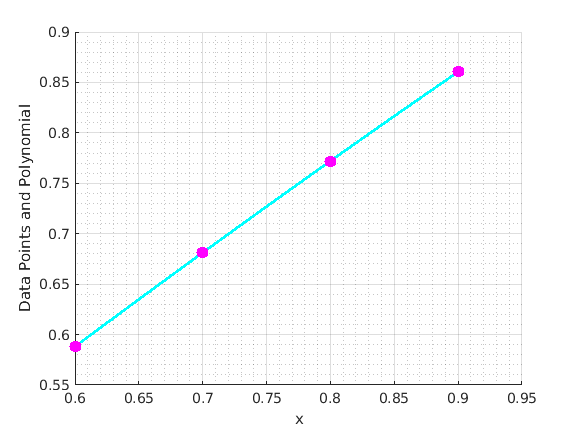

plotPoly(xData, yData, poly)

SOLUTION: (using the solution lagrange function)

xinterps = 0.6:0.01:0.9; 

yy_ans = Lagrange(xData, yData, xinterps)

yy_ans =    0.588120000000000   0.597522940000000   0.606905920000000   0.616268680000000   0.625610960000000   0.634932500000000   0.644233040000000   0.653512320000000   0.662770080000000   0.672006060000000   0.681220000000000   0.690411640000000   0.699580720000000   0.708726980000000   0.717850160000000   0.726950000000000   0.736026240000000   0.745078620000000   0.754106880000000   0.763110760000000   0.772090000000000   0.781044340000000   0.789973520000000   0.798877280000000   0.807755360000000   0.816607500000000   0.825433440000000   0.834232920000000   0.843005680000000   0.851751460000000   0.860470000000000


yy_mine = calcPoly(poly, sym(xinterps))

$$yy\_mine = \left(\begin{array}{ccccccccccccccccccccccccccccccc} \frac{14703}{25000} & \frac{29876147}{50000000} & \frac{1896581}{3125000} & \frac{15406717}{25000000} & \frac{7820137}{12500000} & \frac{253973}{400000} & \frac{8052913}{12500000} & \frac{1021113}{1562500} & \frac{4142313}{6250000} & \frac{33600303}{50000000} & \frac{34061}{50000} & \frac{17260291}{25000000} & \frac{8744759}{12500000} & \frac{35436349}{50000000} & \frac{8973127}{12500000} & \frac{14539}{20000} & \frac{1150041}{1562500} & \frac{37253931}{50000000} & \frac{294573}{390625} & \frac{19077769}{25000000} & \frac{77209}{100000} & \frac{39052217}{50000000} & \frac{9874669}{12500000} & \frac{4992983}{6250000} & \frac{5048471}{6250000} & \frac{326643}{400000} & \frac{5158959}{6250000} & \frac{20855823}{25000000} & \frac{10537571}{12500000} & \frac{42587573}{50000000} & \frac{86047}{100000} \end{array}\right)$$

yy_mine_double = double(vpa(yy_mine))

yy_mine_double =    0.588120000000000   0.597522940000000   0.606905920000000   0.616268680000000   0.625610960000000   0.634932500000000   0.644233040000000   0.653512320000000   0.662770080000000   0.672006060000000   0.681220000000000   0.690411640000000   0.699580720000000   0.708726980000000   0.717850160000000   0.726950000000000   0.736026240000000   0.745078620000000   0.754106880000000   0.763110760000000   0.772090000000000   0.781044340000000   0.789973520000000   0.798877280000000   0.807755360000000   0.816607500000000   0.825433440000000   0.834232920000000   0.843005680000000   0.851751460000000   0.860470000000000


% COMPARE - they are the same
isequal(yy_ans, yy_mine_double) % even though this says

ans = logical
   0


% they are NOT, they actually appear equal... (below)

[yy_ans; yy_mine_double]'

ans =    0.588120000000000   0.588120000000000
   0.597522940000000   0.597522940000000
   0.606905920000000   0.606905920000000
   0.616268680000000   0.616268680000000
   0.625610960000000   0.625610960000000
   0.634932500000000   0.634932500000000
   0.644233040000000   0.644233040000000
   0.653512320000000   0.653512320000000
   0.662770080000000   0.662770080000000
   0.672006060000000   0.672006060000000
   0.681220000000000   0.681220000000000
   0.690411640000000   0.690411640000000
   0.699580720000000   0.699580720000000
   0.708726980000000   0.708726980000000
   0.717850160000000   0.717850160000000
   0.726950000000000   0.726950000000000
   0.736026240000000   0.736026240000000
   0.745078620000000   0.745078620000000
   0.754106880000000   0.754106880000000
   0.763110760000000   0.763110760000000
   0.772090000000000   0.772090000000000
   0.781044340000000   0.781044340000000
   0.789973520000000   0.789973520000000
   0.798877280000000   0.798877280000000
   0.80775